# Run Param_lab3_real.mlx

## Run General parameter

step_amplitude = 50;

# Simulate step 50 [deg] lqr bryson (lab3_lqr_bryson_box_sim.slx ) or real

## Salva dati 50 deg lqr bryson 


t = ScopeData1.time;
tetha_h = ScopeData1.signals(1).values;  
tetha_d = ScopeData1.signals(2).values;
ref_signal = ScopeData1.signals(3).values;
command_u =  ScopeData1.signals(4).values;

save("lab3_lqr__Bryson_sim_box.mat",'t','tetha_h','tetha_d','ref_signal','command_u');


## Stampa grafico

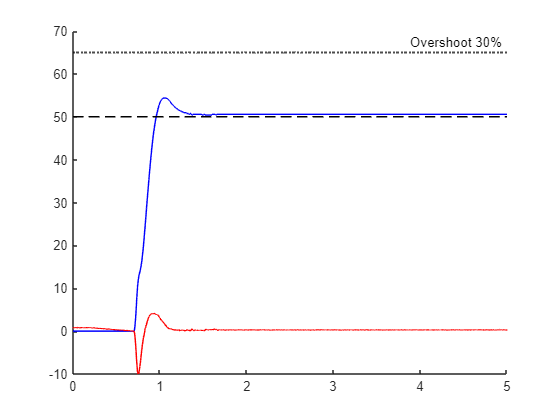

% grafico step 50 deg

load("lab3_lqr__Bryson_sim_box.mat");

figure;
% plot(t,ref,'k--');
yline(65, 'k:','LineWidth', 1.5, 'Label', 'Overshoot 30%');
hold on 
plot(t,tetha_h,'b');
plot(t,tetha_d,'r');
plot(t,ref_signal,'k--');
axis([0 5 -10 70])
hold off

#### Step response parameters


step_50_wind_up_nominal_lqr = stepinfo(tetha_h, t, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr);

         RiseTime: 0.1879
    TransientTime: 1.1489
     SettlingTime: 1.1489
      SettlingMin: 45.1800
      SettlingMax: 54.3600
        Overshoot: 8.7200
       Undershoot: 0
             Peak: 54.3600
         PeakTime: 1.0220



## grafico step 50 deg per verificare tetha_h - 50 < 0.3 * 50

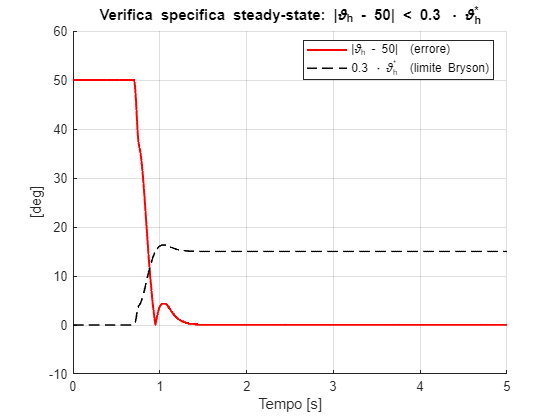


figure;
hold on
plot(t, abs(tetha_h - 50), 'r', 'LineWidth', 1.5);
plot(t, tetha_h * 0.3, 'k--', 'LineWidth', 1.2);
hold off
axis([0 5 -10 60])
grid on
xlabel('Tempo [s]')
ylabel('[deg]')
title('Verifica specifica steady-state: |\vartheta_h - 50| < 0.3 \cdot \vartheta_h^*')
legend('|\vartheta_h - 50|  (errore)', ...
       '0.3 \cdot \vartheta_h^*  (limite Bryson)', ...
       'Location', 'best')

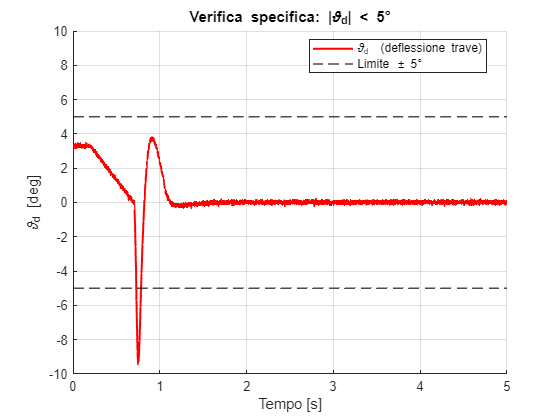




figure;
hold on
plot(t, tetha_d, 'r', 'LineWidth', 1.5);
yline(5,  'k--', 'LineWidth', 1.2, 'HandleVisibility', 'off');
yline(-5, 'k--', 'LineWidth', 1.2);
hold off
axis([0 5 -10 10])
grid on
xlabel('Tempo [s]')
ylabel('\vartheta_d [deg]')
title('Verifica specifica: |\vartheta_d| < 5°')
legend('\vartheta_d  (deflessione trave)', ...
       'Limite \pm 5°', ...
       'Location', 'best')

## grafico step 50 deg per verificare u < 10

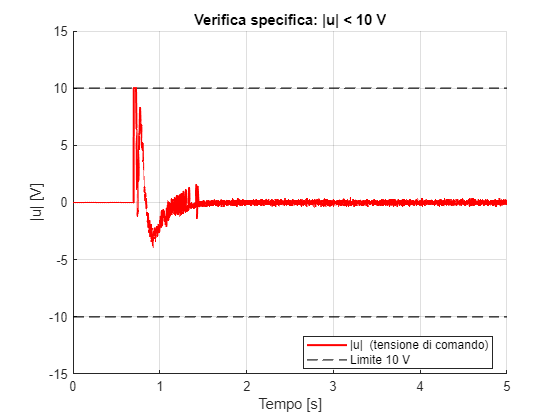



figure;
hold on
plot(t, command_u, 'r', 'LineWidth', 1.5);
yline(10, 'k--', 'LineWidth', 1.2);
yline(-10, 'k--', 'LineWidth', 1.2);
hold off
axis([0 5 -15 15])
grid on
xlabel('Tempo [s]')
ylabel('|u| [V]')
title('Verifica specifica: |u| < 10 V')
legend('|u|  (tensione di comando)', ...
       'Limite 10 V', ...
       'Location', 'best')